clc;
clear;
close all;

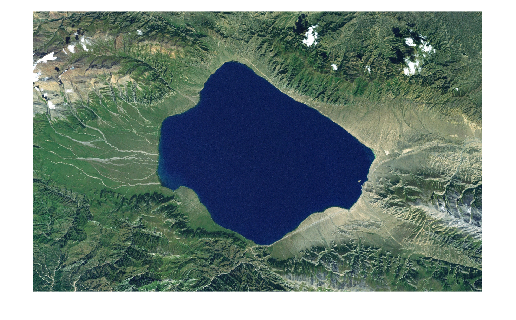

img = imread("Lake.png");
imshow(img);

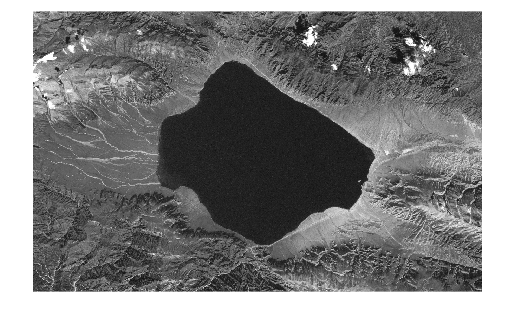

gray_img = rgb2gray(img);
imshow(gray_img);

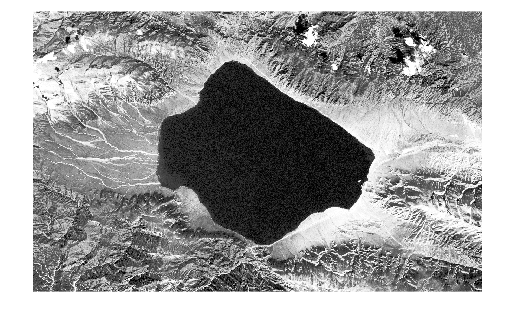

heqgray = histeq(gray_img);
imshow(heqgray);

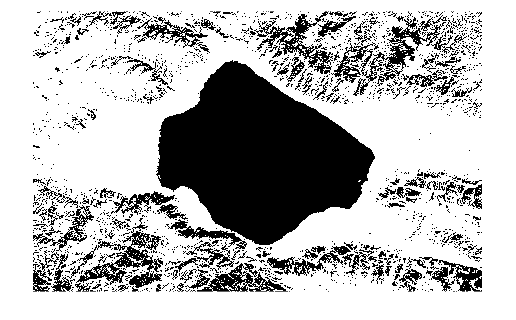

thres=.35;
BWimg = imbinarize(heqgray,thres);
imshow(BWimg);

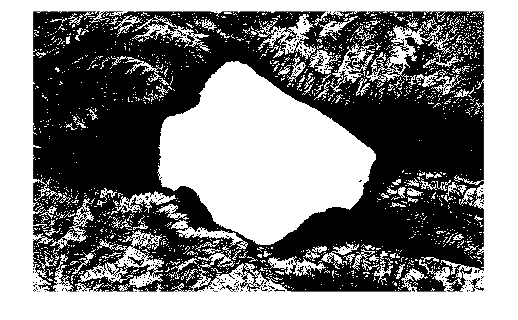

BW_inverted=imcomplement(BWimg);
imshow(BW_inverted);

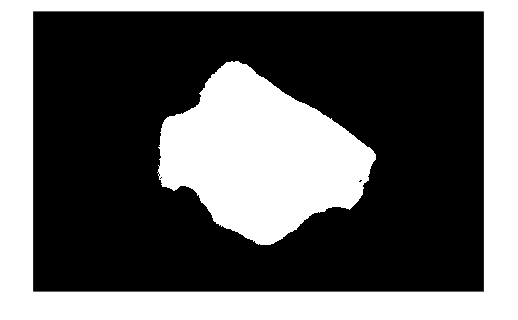

n_area=1;
out_img = bwareafilt(BW_inverted,n_area);
imshow(out_img);